# **Initial Sizing and Baseline Evo**

% House Keeping
clear
clc
close all

**Basic Parameters**

% Weight
W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8

% W_0 = 0;                               % Takeoff gross weight (kg)
% W_f_0 = 0;                             % W_fuel / W_0
% W_e_0 = 0;                             % W_empty weight / W_0

[T_0, c_0, P_0, rho_0] = atmosisa(0);    % Sea-level condition

g = 9.80665;                             % Standard acceleration of gravity (m/s^2)

**Mission Profile**

first cruise

% since the cruise condition is not specified in given mission
% profile, assume first cruise will be held in cruise-climb to
% maximise the fuel efficiency of the aircraft [Intro to Aero p.117]
h_cruise1 = 26000; % first cruise average altitude (ft)
[T_cruise1, c_cruise1, P_cruise1, rho_cruise1] = atmosisa(convlength(h_cruise1, 'ft','m'));
V_cruise1 = 0.83;

second cruise

h_cruise2 = 18000; % Cruise altitude (ft) for Lost Communications Missed Approach % Ref 5

V_cruise2 = convvel(400, 'kts', 'm/s'); % Assume cruise velocity 400 knots % Ref 5
[T_cruise2, c_cruise2, P_cruise2, rho_cruise2] = atmosisa(convlength(h_cruise2, 'ft','m'));
V_cruise2 = V_cruise2 ./ c_cruise2;

absolute ceiling

absCeiling = convlength(45000,'ft','m'); % Absolute Ceiling

loiter

h_loiter = convlength(5000, 'ft','m'); % Alternate altitude (m)

[T_loiter, c_loiter, P_loiter, rho_loiter] = atmosisa(h_loiter);

**Empirical Airplane Data**

AR = 7.6;         % Aspect ratio
WR = 5.5;          % S_wet / S_ref         % Raymer p.40
AR_W = AR ./ WR;   % Wetted aspect ratio
K_LD = 15.5;       % For civil jets        % Raymer p.40
LD_max = K_LD .* (AR_W) .^ 0.5; % L/D_max  % Raymer p.41

CD_0 = 0.023;  % Drag ceofficient at zero lift % Boeing 777-300ER
e = 0.85;      % Oswald/span efficiency factor % Boeing 777-300ER
CL_max_L = 2.69;             % Maximum lift coefficient in landing configuration
CL_max_TO = CL_max_L .* 0.8; % Maximum lift coefficient in take-off configuration
CL_max_C = 1.4;              % Maximum lift coefficient in cruise configuration

V_S = convvel(137, 'kts', 'm/s'); % Stall speed at sea level % Boeing 777-300ER
V_A = 1.3 * V_S;                  % Approach speed at sea level % Raymer p.110
V_TO = 1.2 * V_S;                 % Take off velocity (m/s)

**Empirical Engine Data**

NE = 4; % Number of engines

High-bypass Turbofan

C_cruise = 0.5 ./ 3600; % SFC (1/s) % Raymer p.36

Trent 972E-84 

% W_engine = 9630; % Weight of engine (kg)
T_0 = 320300;      % Takeoff thrust (N)
T_0 = T_0 * 1.05;  % Rubber engine
% BPR = 8.5;       % Bypass Ratio % Trent 972E-84 % Ref 17

**Calculate Fuel Fraction **

[W_f_0, W_i] = Wf_W0(h_cruise1, h_cruise2, V_cruise1, V_cruise2, LD_max, C_cruise);

 Plot table for fuel fraction 

col1 = ["0-1", "1-2", "2-3", "3-4", "4-5", "5-6", "6-7", "7-8", "8-9"];
col2 = [W_i(1), W_i(2), W_i(3), W_i(4), W_i(5), W_i(6), W_i(7), W_i(8), W_i(9)];
col3 = cumprod(col2);
T = table(col1', col2', col3', 'VariableNames', {'Leg', 'Wi/Wi-1', 'Culmulative'});
disp(T)

     Leg     Wi/Wi-1    Culmulative
    _____    _______    ___________

    "0-1"       0.97         0.97  
    "1-2"      0.985      0.95545  
    "2-3"    0.62023       0.5926  
    "3-4"       0.99      0.58667  
    "4-5"    0.98962      0.58058  
    "5-6"    0.97203      0.56434  
    "6-7"    0.98367      0.55512  
    "7-8"    0.99308      0.55128  
    "8-9"      0.992      0.54687  



W_f_0

W_f_0 = 0.4577

**Calculate Empty Weight Fraction**

% Guess Takeoff gross weight (kg)
W_0 = zeros(2000, 1);

for i = 1:2000
    W_0(i) = 100000 + 750 * i;
end

From regression of historical data (Raymer p.31)


$$\frac{W_E }{W_0 }={\textrm{AW}}_o^C$$


A_Ry = 0.97;  % Constant from jet transport historical data % Raymer p.31
C_Ry = -0.06; % Constant from jet transport historical data % Raymer p.31
W_e_0_Ry = A_Ry .* W_0 .^ C_Ry;

Composite material (Raymer p.51)

W_e_0 = 0.95 * W_e_0_Ry;

**Estimate Takeoff Gross Weight**

% From weight build-up calculations
W_e_0_Cal = 1 - W_f_0 - (W_crew + W_payload) ./ W_0; % Raymer p.34

% Caculate exact value of solution
func_Ry = @(W0) ((W_crew + W_payload) / (1 - W_f_0 - 0.95 .* (A_Ry * W0 ^ C_Ry))) - W0;
W0_initial_guess = 4000000; % Adjust based on expected range
W_0 = fsolve(func_Ry, W0_initial_guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


% Output result
W_0

W_0 = 4.3093e+05

W_e_0 = 1 - W_f_0 - (W_crew + W_payload) ./ W_0

W_e_0 = 0.4231

W_e = W_e_0 * W_0

W_e = 1.8232e+05

W_f = W_f_0 * W_0

W_f = 1.9722e+05

**Specific Excess Power (SEP)**


$${\left(\frac{\mathit{\mathbf{T}}}{\mathit{\mathbf{W}}}\right)}_0 =\frac{\alpha }{\beta }\left(\frac{1}{V_{\infty } }\frac{\mathbf{dh}}{\mathbf{dt}}+\frac{1}{\mathit{\mathbf{g}}}\frac{{\mathbf{dV}}_{\infty } }{\mathbf{dt}}+\frac{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 {\mathit{\mathbf{C}}}_{{\mathit{\mathbf{D}}}_0 } }{\frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\mathbf{ref}} }}+\frac{{\mathit{\mathbf{n}}}^2 \frac{\mathit{\mathbf{W}}}{{\mathit{\mathbf{S}}}_{\mathbf{ref}} }}{\frac{1}{2}\rho {{\mathit{\mathbf{V}}}_{\infty } }^2 \pi \mathbf{ARe}}\right)$$
 

T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho) ...
    alpha ./ beta .* (1 ./ V .* dh_dt + 1 ./ g .* dV_dt + ...
    (0.5 .* rho .* V .^ 2 .* CD0) ./ (alpha .* W0_Sref) + ...
    (alpha .* n .^ 2 .* W0_Sref) ./ (0.5 .* rho .* V .^ 2 .* pi .* AR .* e));

% Guessed Wing Loading
W0_Sref = linspace(100,15000,500);

**Maximum achievable **${\left(\frac{T}{W}\right)}_0$ (Curve descend with wing loading)

T0_W0_Max = NE * T_0 / (W_0 * g);

**Stall **(Vertical straight line)

W0_Sref_Stall = 0.5 * rho_0 * V_S ^ 2 * CL_max_L;

**Landing with Reverse Device OFF **(Vertical straight line)

sigma = 1;   % Landing site ASL
Sa = 305;    % Airliner type 3 degree glideslope
% KR_2 = 1;  % Correction factor for thrust reverse device
ALD = 2900;  % Runway length (m)

alpha_landing = 0.9;                                                    % Immediate landing after takeoff
% W_S_Landing = g * (ALD * 0.6 - Sa) * (sigma * CL_max_L) / (0.51 * g); % Regression data % www.aircraftinvestigation.info
% W0_S_Landing = W_S_Landing / alpha_landing;

W0_S_Landing = (g * (ALD * 0.6 - Sa) * (sigma * CL_max_L) / (0.51 * g)) / alpha_landing;

**1st Cruise **(Curve descend with wing loading)

T0_W0_cruise1 = Constraint_Cruise(h_cruise1, V_cruise1, W0_Sref, W_i(1) * W_i(2), AR, e, CD_0);

**2nd Cruise **(Curve descend with wing loading)

T0_W0_cruise2 = Constraint_Cruise(h_cruise2, V_cruise2, W0_Sref, W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5), AR, e, CD_0);

**Cruise at maximum speed (M = 0.85) **(Curve descend with wing loading)

T0_W0_cruiseMAX = Constraint_Cruise(h_cruise1, 0.85, W0_Sref, W_i(1) * W_i(2), AR, e, CD_0);

**Absolute Ceiling **(Horizontal straight line)ccvcc

% alpha_absCeiling = W_i(1) * W_i(2);      % At the start of cruise 1
% beta_absCeiling = T_T0(absCeiling);      % Ignore effect of M % Intro to Aerospace p.83


$${\left(\frac{T}{W}\right)}_0 =\frac{2\alpha }{\beta \sqrt{\frac{\pi \mathrm{ARe}}{C_{D_0 } }}}$$


% T0_W0_abs = (2 * alpha_absCeiling) / (beta_absCeiling * ((pi * AR * e) / CD_0) ^ 0.5);
T0_W0_abs = (2 * W_i(1) * W_i(2)) / (T_T0(absCeiling) * ((pi * AR * e) / CD_0) ^ 0.5);

**Loiter**

Calculate Indicated Minimum Drag Speed $V_{\mathrm{imD}}$ according to $V_{\mathrm{maxSAR}} =\frac{V_{i\;\mathrm{maxSAR}} }{\sqrt{\sigma }}=\sqrt[4]{3}\frac{V_{\mathrm{imD}} }{\sqrt{\sigma }}$ (Intro to Aerospace p.110)

V_imD = (V_cruise1 .* c_cruise1) .* (rho_cruise1 ./ rho_0) .^ 0.5 ./ ((3) .^ 0.25);

Calculate loitering speed, $V=V_{\mathrm{mD}} =\frac{V_{\mathrm{imD}} }{\sqrt{\sigma }}$

V_mD = V_imD ./ ((rho_loiter ./ rho_0) .^ 0.5);

Calculate ${\left(\frac{T}{W}\right)}_0$

% T0_W0 = @(alpha, beta, dh_dt, dV_dt, W0_Sref, AR, e, V, CD0, n, rho)
T0_W0_loiter = T0_W0(W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6), T_T0(h_loiter), 0.0, 0.0, W0_Sref, AR, e, V_mD, CD_0, 1, rho_loiter);

**Takeoff **(Straight line)

Basic Parameters

sigma = 1;   % Takeoff site ASL
TODA = 2900; % Runway length (m)

Calculate ${\left(\frac{T}{W}\right)}_0$

$\textrm{AEO}$ to 50 ft (FAR 23 not FAR 25)

T0_W0_AEO = 1.15 .* 0.144 .* W0_Sref ./ (sigma * CL_max_TO * TODA);


$$\textrm{BFL}\;4N_E$$
 

T0_W0_BFL = (0.297 - 0.019 * NE) .* W0_Sref ./ (sigma * CL_max_TO * TODA);

**1st Climb and accelerate  **(Horizontal straight line)

*Climbing at 7 degrees (assumption) of slope at *$V_2 =1\ldotp 2V_{\mathrm{Stall}}$

% theta1 = 7 * pi / 180;                 % Climb angle (rad) % twin engine % FAR
dh_dt_climb1 = V_TO * sin(7 * pi / 180); % Climb rate (m/s)

Airplane should reach cruise speed at cruise altitude

T_climb1 = convlength(h_cruise1,'ft','m') / (dh_dt_climb1);  % The climb time assumed constant climb rate (s)
dV_dt_climb1 = (V_cruise1 * c_cruise1 - V_TO) / T_climb1;    % The average acceleration (m/s^2)

Calculate ${\left(\frac{T}{W}\right)}_0$

T0_W0_climb1 = T0_W0(W_i(1), T_T0(0), dh_dt_climb1, dV_dt_climb1, W0_Sref, AR, e, V_TO, CD_0, 1, 1);

**2nd Climb after mised approach**

Refer to **'landing climb'** in FAR25 must not be less than 3.2 degrees

% theta2 = 3.6 * pi / 180;                 % Climb angle (rad) % landing climb % FAR25
dh_dt_climb2 = V_TO * sin(3.6 * pi / 180); % Climb rate (m/s)

Airplane should reach cruise speed at cruise altitude

T_climb2 = convlength(h_cruise2,'ft','m') / (dh_dt_climb2); % The climb time assumed constant climb rate (s)
dV_dt_climb2 = (V_cruise2 * c_cruise2 - V_TO) / T_climb2;   % The average acceleration (m/s^2)

Calculate ${\left(\frac{T}{W}\right)}_0$

T0_W0_climb2 = T0_W0(W_i(1) * W_i(2) * W_i(3) * W_i(4), T_T0(0), dh_dt_climb2, dV_dt_climb2, W0_Sref, AR, e, V_TO, CD_0, 1, 1);

**ICAO Aerodome Reference Code 4E**

Maximum wing span 65 m

W0_S_ICAO = (W_0 .* g) ./ (65 ^ 2 ./ AR)

W0_S_ICAO = 7.6018e+03

Minimum wing span 52 m

W0_S_ICAO_min = (W_0 .* g) ./ (52 ^ 2 ./ AR)

W0_S_ICAO_min = 1.1878e+04

**Constraint Diagram**

% Find the crossing point

T0_W0_Selected = (0.297 - 0.019 * NE) .* W0_S_ICAO ./ (sigma * CL_max_TO * TODA)

T0_W0_Selected = 0.2692

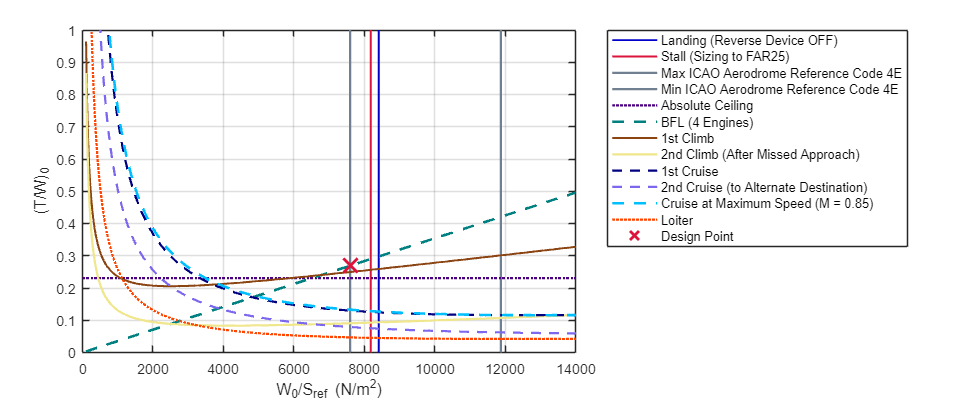


% Plot the constraint diagram

figure(1)

clf;

plot([W0_S_Landing W0_S_Landing], [0 1], '-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25)
hold on % Landing
plot([W0_Sref_Stall W0_Sref_Stall], [0 1], '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25);
hold on % Stall
plot([W0_S_ICAO W0_S_ICAO], [0 1], '-', 'Color', [112/255 128/255 144/255], 'LineWidth', 1.5);
hold on % ICAO Aerodrome Reference Code 4E maximum
plot([W0_S_ICAO_min W0_S_ICAO_min], [0 1], '-', 'Color', [112/255 128/255 144/255], 'LineWidth', 1.5);
hold on % ICAO Aerodrome Reference Code 4E minimum
plot([0 20000], [T0_W0_abs T0_W0_abs], ':', 'Color', [75/255 0/255 130/255], 'LineWidth', 1.5);
hold on % Absolute Ceiling
plot(W0_Sref, T0_W0_BFL, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.75);
hold on % Take-off BFL 4NE
plot(W0_Sref, T0_W0_climb1, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.35);
hold on % 1st Climb
plot(W0_Sref, T0_W0_climb2, '-', 'Color', [240/255 230/255 140/255], 'LineWidth', 1.5);
hold on % 2nd Climb
plot(W0_Sref, T0_W0_cruise1, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on % 1st Cruise
plot(W0_Sref, T0_W0_cruise2, '--', 'Color', [123/255 104/255 238/255], 'LineWidth', 1.5);
hold on % 2nd Cruise
plot(W0_Sref, T0_W0_cruiseMAX, '--', 'Color', [0/255 191/255 255/255], 'LineWidth', 1.75);
hold on % Cruise at M=0.85
plot(W0_Sref, T0_W0_loiter, ':', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.5);
hold on % Loiter
plot(W0_S_ICAO, T0_W0_Selected, 'x', 'Color', [220/255 20/255 60/255], 'MarkerSize', 13.5, 'LineWidth', 1.75)
hold off


legend('Landing (Reverse Device OFF)', 'Stall (Sizing to FAR25)', ...
       'Max ICAO Aerodrome Reference Code 4E', 'Min ICAO Aerodrome Reference Code 4E', ...
       'Absolute Ceiling', 'BFL (4 Engines)',...
       '1st Climb', '2nd Climb (After Missed Approach)', '1st Cruise',...
       '2nd Cruise (to Alternate Destination)', 'Cruise at Maximum Speed (M = 0.85)', 'Loiter', ...
       'Design Point', ...
       'Location', 'northeastoutside', 'NumColumns', 1, FontSize = 8.5)

xlabel('W_{0}/S_{ref} (N/m^{2})'); 
ylabel('(T/W)_{0}');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

xlim([0 14000]);
ylim([0 1]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

**High Lift Device**

Basic Parameters

A = 30 * pi/180;             % Sweep angle (rad)
% W0_Sref_design = W0_S_ICAO; 
Sref = W_0 .* g / W0_S_ICAO; % Reference Area (m^2)
AR_Design = 65 .^ 2 ./ Sref;
cf_c = 1.2;                  % c_flap/c
Sflap_Sref = 0.6;            % S_flap/S_ref

Calculation

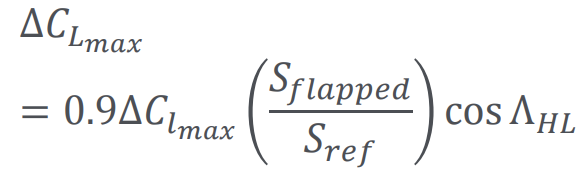

dClmax = [1.3*cf_c, 1.6*cf_c, 1.9*cf_c] % Fowler, Double slotted, Triple slotted

dClmax =     1.5600    1.9200    2.2800


dClmaxLE = [0.2, 0.3, 0.4*cf_c] % Fixed slotted, leading-edge flap, slat

dClmaxLE =     0.2000    0.3000    0.4800


dCLmax = 0.9.*(dClmaxLE(3) + dClmax).*Sflap_Sref*cos(A); % Using slat
%TWRatioBFL = @(W0_Sref,CL_max_TO) 4.45 * 10 ^ (-5) .* W0_Sref*2.034.*0.85./CL_max_TO;
TWRatioBFL = @(W0_Sref,CL_max_TO) (0.297 - 0.019 * NE) .* W0_Sref ./ (sigma * CL_max_TO * TODA);
WL0_Landing = @(ALD,Sa,sigma,CL_max_L,alpha_landing) 9.81 * (ALD * 0.6 - Sa) * (sigma * CL_max_L) / (0.51*9.81)/ alpha_landing; % Regression data % www.aircraftinvestigation.info

CL_max_TO_HLD = 0.8*(CL_max_C + dCLmax);
CL_max_L_HLD = CL_max_C + dCLmax

CL_max_L_HLD =     2.3540    2.5224    2.6907


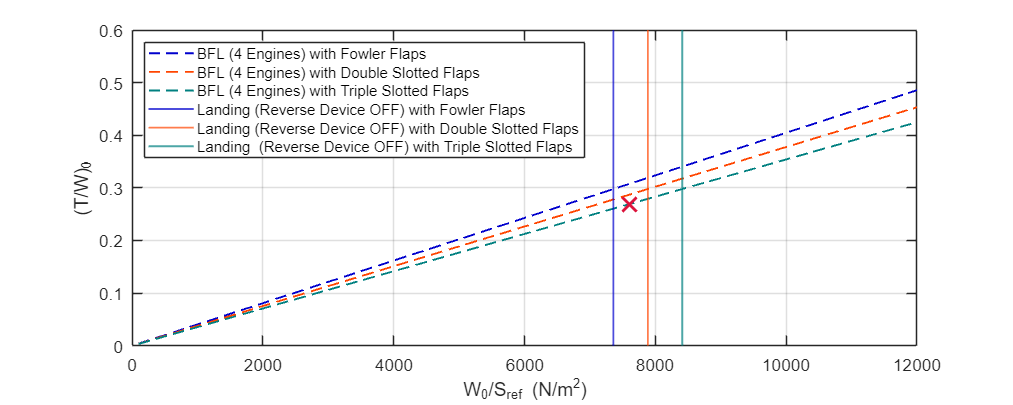


BFLFowler = TWRatioBFL(W0_Sref, CL_max_TO_HLD(1));
BFLDoubleSlotted = TWRatioBFL(W0_Sref, CL_max_TO_HLD(2));
BFLTripleSlotted = TWRatioBFL(W0_Sref, CL_max_TO_HLD(3));

LandingFowler = WL0_Landing(ALD,Sa,sigma,CL_max_L_HLD(1),alpha_landing);
LandingDoubleSlotted = WL0_Landing(ALD,Sa,sigma,CL_max_L_HLD(2),alpha_landing);
LandingTripleSlotted = WL0_Landing(ALD,Sa,sigma,CL_max_L_HLD(3),alpha_landing);

figure(2)
clf;
plot(W0_Sref, BFLFowler, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25)
hold on
plot(W0_Sref, BFLDoubleSlotted,  '--', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
plot(W0_Sref, BFLTripleSlotted, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.25)
hold on
xline(LandingFowler, '-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25)
hold on
xline(LandingDoubleSlotted,  '-', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25)
hold on
xline(LandingTripleSlotted, '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.25)
hold on
plot(W0_S_ICAO, T0_W0_Selected, 'x', 'Color', [220/255 20/255 60/255], 'MarkerSize', 13.5, 'LineWidth', 1.75)
hold off

xlabel('W_{0}/S_ref (N/m^{2})'); 
ylabel('(T/W)_{0}')
legend("BFL (4 Engines) with Fowler Flaps","BFL (4 Engines) with Double Slotted Flaps","BFL (4 Engines) with Triple Slotted Flaps", ...
    "Landing (Reverse Device OFF) with Fowler Flaps","Landing (Reverse Device OFF) with Double Slotted Flaps", ...
    "Landing  (Reverse Device OFF) with Triple Slotted Flaps", "Location", "northwest", 'NumColumns', 1, FontSize = 10)

set(gca, 'FontSize', 11.5) % set the fontsize of the axis

xlim([0 12000]);
ylim([0 0.6]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 900 360]); % show plot with larger size 